# Pro 2D se zavazim

postup (inspirace) dle diplomove prace [*https://dspace.cvut.cz/handle/10467/107394*](https://dspace.cvut.cz/handle/10467/107394) a clanku [*https://www.researchgate.net/publication/338542376_Sliding_Mode-Based_Control_of_a_UAV_Quadrotor_for_Suppressing_the_Cable-Suspended_Payload_Vibration*](https://www.researchgate.net/publication/338542376_Sliding_Mode-Based_Control_of_a_UAV_Quadrotor_for_Suppressing_the_Cable-Suspended_Payload_Vibration) (pro reseni problemu se setrvacnosti kyvadla)

NÁVRH OPTIMÁLNÍHO ŘÍZENÍ PLANÁRNÍHO MODELU UAV S BŘEMENEM

**Predpoklady (jako u me)**

- treni v kloubech je linearne zavisle na rychlosti

- kyvadlo je povazavano za matematicke kyvadlo

- pohyb v 2D rovine

- parametry systemu se nemeni s casem (*time-invariant*)

**Promenne a parametry**

syms x(t) y(t) fi(t) alfa(t) %zobecnene souradnice q
%P.S. v DP vychyleni kvadrokoptery je theta(t), vychyleni zavazi fi(t)
syms M m F1 F2 g L d I Ip F_wind 

Drobne odliseni od mych odvozeni. Misto koef. odporu k (kvadrokoptera) a kp (pendulum) v DP se pouzivaji koeficienty cx, cy, cfi, calfa prislusnych pohybu !

syms c_x c_y c_fi c_alfa 

**"**Pro odvození pohybových rovnic byla použita Eulerova-Lagrangeova rovnice druhého druhu rozšířená o Rayleighovu disipační funkci v následujícím tvaru"


$$\begin{array}{l}
\frac{d}{\textrm{dt}}\left(\frac{\partial \textrm{Lag}}{\partial \overset{\cdot }{q} }\right)-\frac{\partial \textrm{Lag}}{\partial q}+\frac{\partial \textrm{Ray}}{\partial \overset{\cdot }{q} }=Q^{\textrm{nc}} ,\textrm{kde}\\
\textrm{Lag}=E_k -E_p 
\end{array}$$


**Kineticka energia soustavy**

"Kinetická energie systému $E_k$ je rovna součtu kinetických energií každého z těles. Stejně tak lze kinetickou energii tuhého tělesa zapsat podle Königovy věty jako součet translační energie a rotační energie vzhledem k těžišti"

Kvadrokoptera:

w_kin1 = 1/2*M*diff(x, 1)^2 %translacni x

$$w\_kin1(t) = \frac{M\,{\left(\frac{\partial }{\partial t}x\left(t\right)\right)}^{2}}{2}$$

w_kin2 = 1/2*M*diff(y, 1)^2 %translacni y

$$w\_kin2(t) = \frac{M\,{\left(\frac{\partial }{\partial t}y\left(t\right)\right)}^{2}}{2}$$

w_kin3 = 1/2*I*diff(fi, 1)^2 %rotacni fi

$$w\_kin3(t) = \frac{\text{I}\,{\left(\frac{\partial }{\partial t}\mathrm{fi}\left(t\right)\right)}^{2}}{2}$$

Zavazi (matematicke kyvadlo)

xp = x+d*sin(alfa) %poloha teziste zavazi xp (zavisla promenna)

$$xp(t) = x\left(t\right)+d\,\sin\left(\mathrm{alfa}\left(t\right)\right)$$

yp = y-d*cos(alfa) %poloha teziste zavazi yp (zavisla promenna)

$$yp(t) = y\left(t\right)-d\,\cos\left(\mathrm{alfa}\left(t\right)\right)$$


w_kin4 = 1/2*m*diff(xp, 1)^2 %translacni x

$$w\_kin4(t) = \frac{m\,{\left(\frac{\partial }{\partial t}x\left(t\right)+d\,\cos\left(\mathrm{alfa}\left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right)\right)}^{2}}{2}$$

w_kin5 = 1/2*m*diff(yp, 1)^2 %translacni y

$$w\_kin5(t) = \frac{m\,{\left(\frac{\partial }{\partial t}y\left(t\right)+d\,\sin\left(\mathrm{alfa}\left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right)\right)}^{2}}{2}$$

%w_kin6 = 1/2*Ip*diff(alfa, 1)^2 *0 %rotacni alfa <--! V CLANKU NENI !, takze w_kin6=0

Celkova kineticka energie soustavy

E_k = w_kin1+w_kin2+w_kin3+w_kin4+w_kin5

$$E\_k(t) = \frac{m\,{\left(\frac{\partial }{\partial t}y\left(t\right)+d\,\sin\left(\mathrm{alfa}\left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right)\right)}^{2}}{2}+\frac{\text{I}\,{\left(\frac{\partial }{\partial t}\mathrm{fi}\left(t\right)\right)}^{2}}{2}+\frac{M\,{\left(\frac{\partial }{\partial t}x\left(t\right)\right)}^{2}}{2}+\frac{M\,{\left(\frac{\partial }{\partial t}y\left(t\right)\right)}^{2}}{2}+\frac{m\,{\left(\frac{\partial }{\partial t}x\left(t\right)+d\,\cos\left(\mathrm{alfa}\left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right)\right)}^{2}}{2}$$

**Potencialni energie soustavy**

E_p = M*g*y + m*g*yp %puvodne jsem mel m*g*d*cos(alfa) a asi bylo chybne (ano, v clanku take pres yp)

$$E\_p(t) = M\,g\,y\left(t\right)+g\,m\,\left(y\left(t\right)-d\,\cos\left(\mathrm{alfa}\left(t\right)\right)\right)$$

**Rayleighova disipacní funkce**

"Lineární ztráta energie závislá na rychlosti může být řešena pomocí Rayleighovy funkce rozptylu Ray"


$$\textrm{Ray}=\frac{1}{2}c_j \cdot \overset{\cdot }{q_j^2 }$$


Ray = 1/2*c_x*diff(x,1)^2 + 1/2*c_y*diff(y,1)^2 + 1/2*c_fi*diff(fi,1)^2 + 1/2*c_alfa*diff(alfa,1)^2

$$Ray(t) = \frac{c_{\mathrm{alfa}}\,{\left(\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right)\right)}^{2}}{2}+\frac{c_{\mathrm{fi}}\,{\left(\frac{\partial }{\partial t}\mathrm{fi}\left(t\right)\right)}^{2}}{2}+\frac{c_{x}\,{\left(\frac{\partial }{\partial t}x\left(t\right)\right)}^{2}}{2}+\frac{c_{y}\,{\left(\frac{\partial }{\partial t}y\left(t\right)\right)}^{2}}{2}$$

**Lagrangian**

Lag=E_k - E_p

$$Lag(t) = \frac{m\,{\left(\frac{\partial }{\partial t}y\left(t\right)+d\,\sin\left(\mathrm{alfa}\left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right)\right)}^{2}}{2}+\frac{\text{I}\,{\left(\frac{\partial }{\partial t}\mathrm{fi}\left(t\right)\right)}^{2}}{2}+\frac{M\,{\left(\frac{\partial }{\partial t}x\left(t\right)\right)}^{2}}{2}+\frac{M\,{\left(\frac{\partial }{\partial t}y\left(t\right)\right)}^{2}}{2}+\frac{m\,{\left(\frac{\partial }{\partial t}x\left(t\right)+d\,\cos\left(\mathrm{alfa}\left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right)\right)}^{2}}{2}-M\,g\,y\left(t\right)-g\,m\,\left(y\left(t\right)-d\,\cos\left(\mathrm{alfa}\left(t\right)\right)\right)$$

**Zobecnene nekonzervativni sily vzhledem k nezavislym promennym (x, y, fi, alfa)**

Qx = -(F1+F2)*sin(fi) + F_wind

$$Qx(t) = F_{\mathrm{wind}}-\sin\left(\mathrm{fi}\left(t\right)\right)\,\left(F_{1}+F_{2}\right)$$

Qy = (F1+F2)*cos(fi)

$$Qy(t) = \cos\left(\mathrm{fi}\left(t\right)\right)\,\left(F_{1}+F_{2}\right)$$

Qfi = (F1-F2)*L

$$Qfi = L\,\left(F_{1}-F_{2}\right)$$

Qalfa = 0

Qalfa = 0

% odvozenni Q bylo zkontrolovano pomoci virtualnich praci

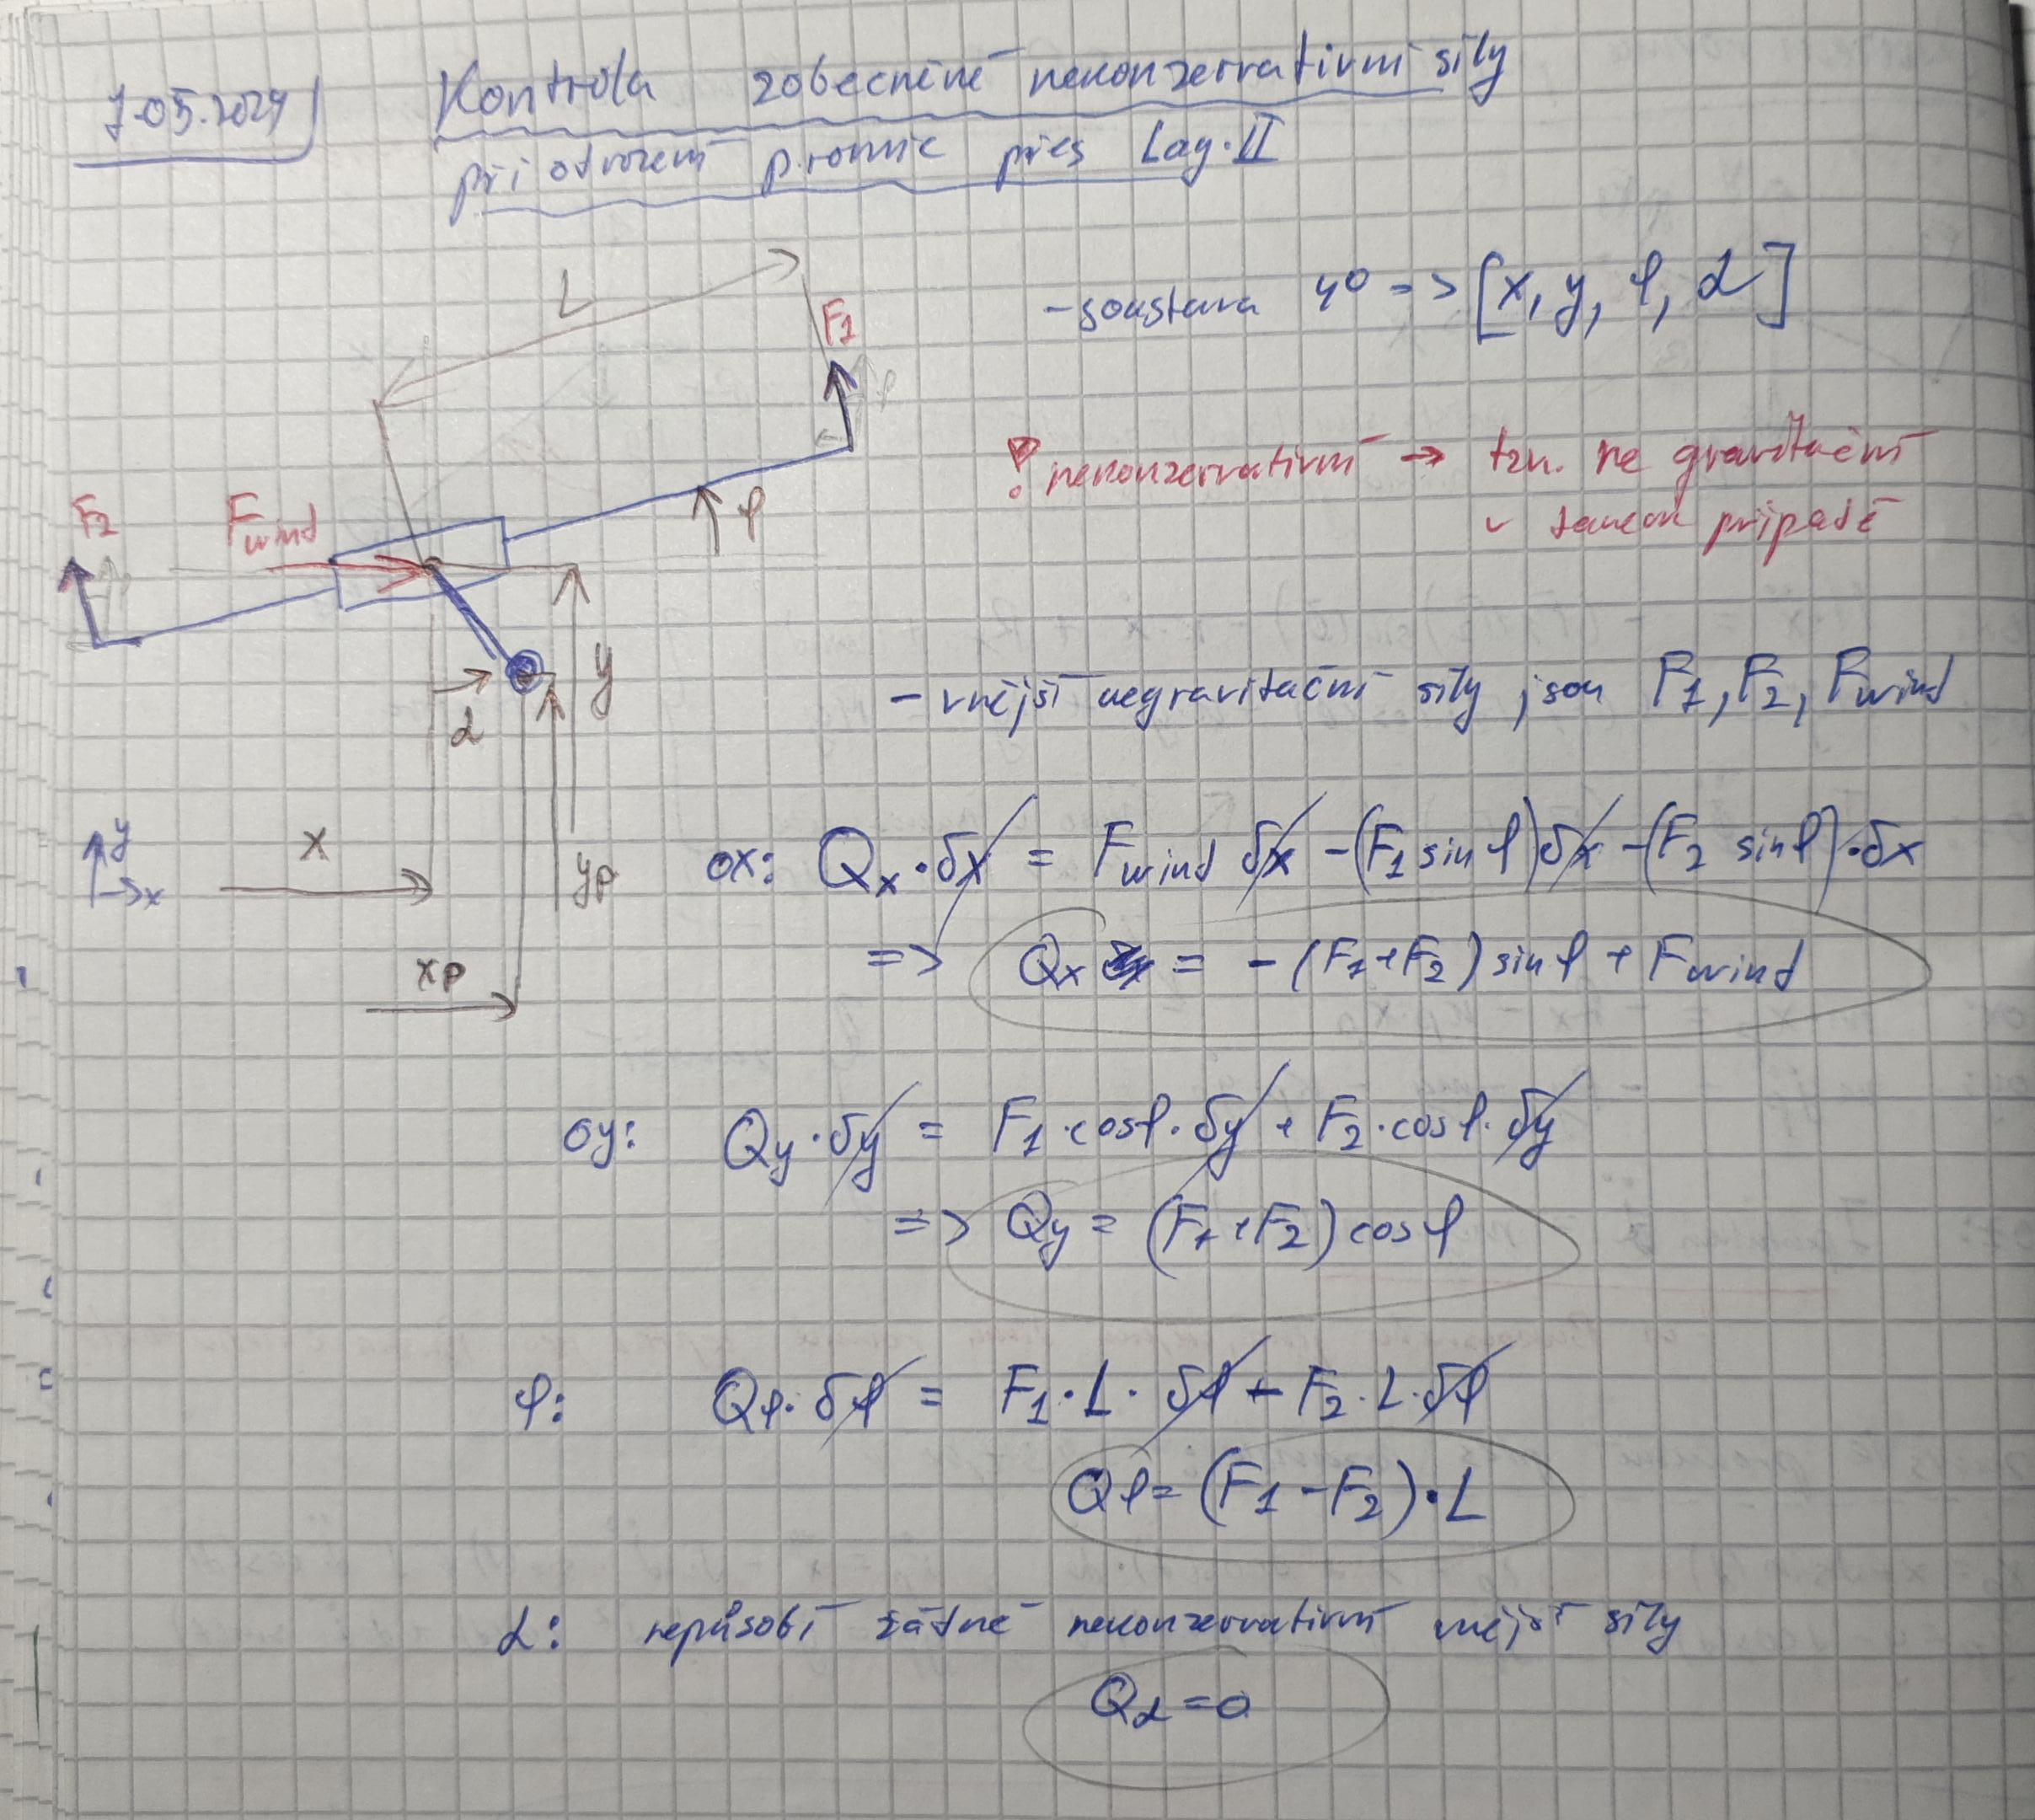

**Eulerova–Lagrangeova rovnice**

eq1 = diff( diff(Lag, diff(x,1)), 1) - diff(Lag, x) + diff(Ray, diff(x,1)) == Qx

$$eq1(t) = c_{x}\,\frac{\partial }{\partial t}x\left(t\right)+M\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+\frac{m\,\left(-2\,d\,\sin\left(\mathrm{alfa}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right)\right)}^{2}+2\,d\,\cos\left(\mathrm{alfa}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\mathrm{alfa}\left(t\right)+2\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)\right)}{2}=F_{\mathrm{wind}}-\sin\left(\mathrm{fi}\left(t\right)\right)\,\left(F_{1}+F_{2}\right)$$

eq2 = diff( diff(Lag, diff(y,1)), 1) - diff(Lag, y) + diff(Ray, diff(y,1)) == Qy

$$eq2(t) = M\,g+g\,m+c_{y}\,\frac{\partial }{\partial t}y\left(t\right)+M\,\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+\frac{m\,\left(2\,d\,\cos\left(\mathrm{alfa}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right)\right)}^{2}+2\,d\,\sin\left(\mathrm{alfa}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\mathrm{alfa}\left(t\right)+2\,\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)\right)}{2}=\cos\left(\mathrm{fi}\left(t\right)\right)\,\left(F_{1}+F_{2}\right)$$

eq3 = diff( diff(Lag, diff(fi,1)), 1) - diff(Lag, fi) + diff(Ray, diff(fi,1)) == Qfi

$$eq3(t) = \text{I}\,\frac{\partial^{2}}{\partial t^{2}}\mathrm{fi}\left(t\right)+c_{\mathrm{fi}}\,\frac{\partial }{\partial t}\mathrm{fi}\left(t\right)=L\,\left(F_{1}-F_{2}\right)$$

eq4 = diff( diff(Lag, diff(alfa,1)), 1) - diff(Lag, alfa) + diff(Ray, diff(alfa,1)) == Qalfa

$$eq4(t) = \begin{array}{l} c_{\mathrm{alfa}}\,\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right)+d\,m\,\cos\left(\mathrm{alfa}\left(t\right)\right)\,\left(d\,\cos\left(\mathrm{alfa}\left(t\right)\right)\,\sigma_{2}-d\,\sin\left(\mathrm{alfa}\left(t\right)\right)\,\sigma_{1}+\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)\right)+d\,m\,\sin\left(\mathrm{alfa}\left(t\right)\right)\,\left(d\,\cos\left(\mathrm{alfa}\left(t\right)\right)\,\sigma_{1}+d\,\sin\left(\mathrm{alfa}\left(t\right)\right)\,\sigma_{2}+\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)\right)+d\,g\,m\,\sin\left(\mathrm{alfa}\left(t\right)\right)=0\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right)\right)}^{2}\\ \sigma_{2}=\frac{\partial^{2}}{\partial t^{2}}\mathrm{alfa}\left(t\right) \end{array}$$

% |
% |
% V
% rucne zjednoduseni rovnic (pozor, bez Ip), vic word soubor (1. stranka)
eq1 = c_x*diff(x,1)+M*diff(x,2)+m*diff(x,2)+m*d*cos(alfa)*diff(alfa,2)-m*d*sin(alfa)*diff(alfa,1)^2 == F_wind-sin(fi)*(F1+F2)

$$eq1(t) = m\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+c_{x}\,\frac{\partial }{\partial t}x\left(t\right)+M\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)-d\,m\,\sin\left(\mathrm{alfa}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right)\right)}^{2}+d\,m\,\cos\left(\mathrm{alfa}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\mathrm{alfa}\left(t\right)=F_{\mathrm{wind}}-\sin\left(\mathrm{fi}\left(t\right)\right)\,\left(F_{1}+F_{2}\right)$$

eq2 = (M+m)*g+c_y*diff(y,1)+M*diff(y,2)+m*diff(y,2)+m*d*sin(alfa)*diff(alfa,2)+m*d*cos(alfa)*diff(alfa,1)^2 == cos(fi)*(F1+F2)

$$eq2(t) = m\,\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+c_{y}\,\frac{\partial }{\partial t}y\left(t\right)+g\,\left(M+m\right)+M\,\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+d\,m\,\cos\left(\mathrm{alfa}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right)\right)}^{2}+d\,m\,\sin\left(\mathrm{alfa}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\mathrm{alfa}\left(t\right)=\cos\left(\mathrm{fi}\left(t\right)\right)\,\left(F_{1}+F_{2}\right)$$

eq3 = eq3

$$eq3(t) = \text{I}\,\frac{\partial^{2}}{\partial t^{2}}\mathrm{fi}\left(t\right)+c_{\mathrm{fi}}\,\frac{\partial }{\partial t}\mathrm{fi}\left(t\right)=L\,\left(F_{1}-F_{2}\right)$$

eq4 = c_alfa*diff(alfa,1)+m*d^2*diff(alfa,2)+m*d*cos(alfa)*diff(x,2)+m*d*sin(alfa)*diff(y,2)+m*g*d*sin(alfa)==0

$$eq4(t) = c_{\mathrm{alfa}}\,\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right)+d^{2}\,m\,\frac{\partial^{2}}{\partial t^{2}}\mathrm{alfa}\left(t\right)+d\,m\,\cos\left(\mathrm{alfa}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+d\,m\,\sin\left(\mathrm{alfa}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+d\,g\,m\,\sin\left(\mathrm{alfa}\left(t\right)\right)=0$$

%v eq4 jsem rucne roznasobil zavorky a zkratil jsem siny a cosiny.

% ddx = isolate(eq1, diff(x, 2))
% ddy = isolate(eq2, diff(y, 2))
% ddfi = isolate(eq3, diff(fi, 2))
% ddalfa = isolate(eq4, diff(alfa, 2))

DALE JSEM UDELAL POROVNANI ROVNIC: **moje VS rovnice v DP**

ale aby obe soustavy se shodovali, rovnice z DP musim upravit a to tak, ze

- m3=m4=0 %nemame voziky

- a2=a3=0 %rotace kvadrokoptery probiha v stredu hmotnosti

vic WORD soubor *poznamka_k_pokus_Lagrange_2*

%   |
%   |
%   V

Super, rovnice se shodhuji

ALE JE OTEVRENA OTAZKA, MUSIM LI UVAZOVAT w_kin6?  Kvuli nej vzika Ip v (Ip+md^2) v eq4 --> ***Bylo mnou rozhodnuto, ze w_kin6 neuvazuji, a to dle clanku vyse. OTAZKA JE ZAVRENA***

**Rovnice v maticovem tvaru**

"Sadu obyčejných diferenciálních rovnic druhého řádu lze také znázornit ve stručnější a přehlednější maticové formě"


$$M\left(q\right)\cdot \overset{\cdot \cdot }{q} +\left(C+G\left(\overset{\cdot }{q} \right)\right)\cdot \overset{\cdot }{q} +Q\left(q\right)=L\left(q\right)\cdot u$$


vstupy u=[T, M, Fwind]' = [(F1+F2), (F1-F2)*L, Fwind]' celkova tahova sila, moment a vitr

qq = [x; y; fi; alfa]

$$qq(t) = \left(\begin{array}{c} x\left(t\right)\\ y\left(t\right)\\ \mathrm{fi}\left(t\right)\\ \mathrm{alfa}\left(t\right) \end{array}\right)$$


MM = [ (M+m)   0   0   m*d*cos(alfa);
       0    (M+m) 0   m*d*sin(alfa);
       0      0   I        0
 m*d*cos(alfa) m*d*sin(alfa) 0 m*d^2]

$$MM(t) = \left(\begin{array}{cccc} M+m & 0 & 0 & d\,m\,\cos\left(\mathrm{alfa}\left(t\right)\right)\\ 0 & M+m & 0 & d\,m\,\sin\left(\mathrm{alfa}\left(t\right)\right)\\ 0 & 0 & \text{I} & 0\\ d\,m\,\cos\left(\mathrm{alfa}\left(t\right)\right) & d\,m\,\sin\left(\mathrm{alfa}\left(t\right)\right) & 0 & d^{2}\,m \end{array}\right)$$


CC = [c_x 0 0 0; 0 c_y 0 0; 0 0 c_fi 0; 0 0 0 c_alfa]

$$CC = \left(\begin{array}{cccc} c_{x} & 0 & 0 & 0\\ 0 & c_{y} & 0 & 0\\ 0 & 0 & c_{\mathrm{fi}} & 0\\ 0 & 0 & 0 & c_{\mathrm{alfa}} \end{array}\right)$$


GG = [0 0 0 -m*d*sin(alfa)*diff(alfa,1);
     0 0 0 m*d*cos(alfa)*diff(alfa,1);
     0 0 0 0;
     0 0 0 0]

$$GG(t) = \left(\begin{array}{cccc} 0 & 0 & 0 & -d\,m\,\sin\left(\mathrm{alfa}\left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right)\\ 0 & 0 & 0 & d\,m\,\cos\left(\mathrm{alfa}\left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right)\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$


QQ = [0; (M+m)*g; 0; m*g*d*sin(alfa)]

$$QQ(t) = \left(\begin{array}{c} 0\\ g\,\left(M+m\right)\\ 0\\ d\,g\,m\,\sin\left(\mathrm{alfa}\left(t\right)\right) \end{array}\right)$$


LL = [-sin(fi) 0 1; cos(fi) 0 0; 0 1 0; 0 0 0]

$$LL(t) = \left(\begin{array}{ccc} -\sin\left(\mathrm{fi}\left(t\right)\right) & 0 & 1\\ \cos\left(\mathrm{fi}\left(t\right)\right) & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 0 \end{array}\right)$$


inputs = [F1+F2; (F1-F2)*L; F_wind]

$$inputs = \left(\begin{array}{c} F_{1}+F_{2}\\ L\,\left(F_{1}-F_{2}\right)\\ F_{\mathrm{wind}} \end{array}\right)$$

**Porovnani vychozich rovnic s rovnicemi z matic** (po roznasobeni), tim zkontrolujeme spravnost jednotlivych matic --> ano se shoduji, vic WORD soubor

[eq1;eq2;eq3;eq4]

$$ans(t) = \begin{array}{l} \left(\begin{array}{c} m\,\sigma_{2}+c_{x}\,\frac{\partial }{\partial t}x\left(t\right)+M\,\sigma_{2}-d\,m\,\sin\left(\mathrm{alfa}\left(t\right)\right)\,\sigma_{4}+d\,m\,\cos\left(\mathrm{alfa}\left(t\right)\right)\,\sigma_{3}=F_{\mathrm{wind}}-\sin\left(\mathrm{fi}\left(t\right)\right)\,\left(F_{1}+F_{2}\right)\\ m\,\sigma_{1}+c_{y}\,\frac{\partial }{\partial t}y\left(t\right)+g\,\left(M+m\right)+M\,\sigma_{1}+d\,m\,\cos\left(\mathrm{alfa}\left(t\right)\right)\,\sigma_{4}+d\,m\,\sin\left(\mathrm{alfa}\left(t\right)\right)\,\sigma_{3}=\cos\left(\mathrm{fi}\left(t\right)\right)\,\left(F_{1}+F_{2}\right)\\ \text{I}\,\frac{\partial^{2}}{\partial t^{2}}\mathrm{fi}\left(t\right)+c_{\mathrm{fi}}\,\frac{\partial }{\partial t}\mathrm{fi}\left(t\right)=L\,\left(F_{1}-F_{2}\right)\\ c_{\mathrm{alfa}}\,\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right)+d^{2}\,m\,\sigma_{3}+d\,m\,\cos\left(\mathrm{alfa}\left(t\right)\right)\,\sigma_{2}+d\,m\,\sin\left(\mathrm{alfa}\left(t\right)\right)\,\sigma_{1}+d\,g\,m\,\sin\left(\mathrm{alfa}\left(t\right)\right)=0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)\\ \sigma_{2}=\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)\\ \sigma_{3}=\frac{\partial^{2}}{\partial t^{2}}\mathrm{alfa}\left(t\right)\\ \sigma_{4}={\left(\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right)\right)}^{2} \end{array}$$

%VS //vysledky z Matlab kontroluju ve Word, je to prehledneji
eqall = MM*diff(qq, 2) + (CC+GG)*diff(qq, 1) + QQ == LL*inputs

$$eqall(t) = \begin{array}{l} \left(\begin{array}{c} c_{x}\,\frac{\partial }{\partial t}x\left(t\right)+\left(M+m\right)\,\sigma_{4}-d\,m\,\sin\left(\mathrm{alfa}\left(t\right)\right)\,\sigma_{2}+d\,m\,\cos\left(\mathrm{alfa}\left(t\right)\right)\,\sigma_{1}=F_{\mathrm{wind}}-\sin\left(\mathrm{fi}\left(t\right)\right)\,\left(F_{1}+F_{2}\right)\\ c_{y}\,\frac{\partial }{\partial t}y\left(t\right)+\left(M+m\right)\,\sigma_{3}+g\,\left(M+m\right)+d\,m\,\cos\left(\mathrm{alfa}\left(t\right)\right)\,\sigma_{2}+d\,m\,\sin\left(\mathrm{alfa}\left(t\right)\right)\,\sigma_{1}=\cos\left(\mathrm{fi}\left(t\right)\right)\,\left(F_{1}+F_{2}\right)\\ \text{I}\,\frac{\partial^{2}}{\partial t^{2}}\mathrm{fi}\left(t\right)+c_{\mathrm{fi}}\,\frac{\partial }{\partial t}\mathrm{fi}\left(t\right)=L\,\left(F_{1}-F_{2}\right)\\ c_{\mathrm{alfa}}\,\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right)+d^{2}\,m\,\sigma_{1}+d\,m\,\cos\left(\mathrm{alfa}\left(t\right)\right)\,\sigma_{4}+d\,m\,\sin\left(\mathrm{alfa}\left(t\right)\right)\,\sigma_{3}+d\,g\,m\,\sin\left(\mathrm{alfa}\left(t\right)\right)=0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}\mathrm{alfa}\left(t\right)\\ \sigma_{2}={\left(\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right)\right)}^{2}\\ \sigma_{3}=\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)\\ \sigma_{4}=\frac{\partial^{2}}{\partial t^{2}}x\left(t\right) \end{array}$$

**Nelinearni stavovy popis**

% diffall = inv(MM)*( -(CC+GG)*diff(qq, 1)-QQ+LL*inputs )
% !!! x = A\b is computed differently than x = inv(A)*b and is recommended
% for solving systems of linear equations. !!!
%|
%V

Porovnal jsem rovnice `diffall`, ktere se lisi pouze v miste, jak invertuji matici MM

Obe rovnice jsou silene, ale maji ulne stejny prubeh. Asi podle me inv(MM)*(...) je kratsi, ale (MM)\(...) je prehlednejsi

diffall = (MM)\( -(CC+GG)*diff(qq, 1)-QQ+LL*inputs )



% [x1, x2, x3, x4, x5, x6, x7, x8] = [x, y, fi, alfa, x_dot, y_dot, fi_dot, alfa_dot]
syms x1 x2 x3 x4 x5 x6 x7 x8
diffall = subs(diffall, [diff(x, 1), diff(y, 1), diff(fi, 1), diff(alfa,1), x, y, fi, alfa], [x5, x6, x7, x8, x1, x2, x3, x4])

subs(diffall, [c_x,c_y,c_fi, c_alfa], [0 0 0 0])

Matice A a B podle DP

% I = eye(4); 
% Z4x4 = zeros(4); 
% Z4x3 = zeros(4, 3);
% I = subs(I, 1, 1); %matice symbolnych 1
% Z4x4 = subs(Z4x4, 0, 0); %matice symbolnych 0 4x4
% Z4x3 = subs(Z4x3, 0, 0) %matice symbolnych 0 4x3
% A = [Z4x4 I; Z4x4 -inv(MM)*(CC+GG)]
% B = [Z4x3; inv(MM)*LL]
% 
% %stavovy popis
% 
% qq = qq;
% qqdot = diff(qq, 1);
% XX = [qq;qqdot]
% 
% ss = diff(XX, 1)==A*XX+B*inputs